# **Global Geometry of Orthogonal Foliations in the Control Allocation of Signed-Quadratic Systems**

rank(A) = 4
dim ker(A) = 2
Selected layer= 6
Selected C= 20
bA = -4.082483e-01
bA = 4.082483e-01
bA = -4.082483e-01
bA = 4.082483e-01
bA = -4.082483e-01
bA = 4.082483e-01
rank(Aaug) = 5
    -1     1    -1     1    -1     1



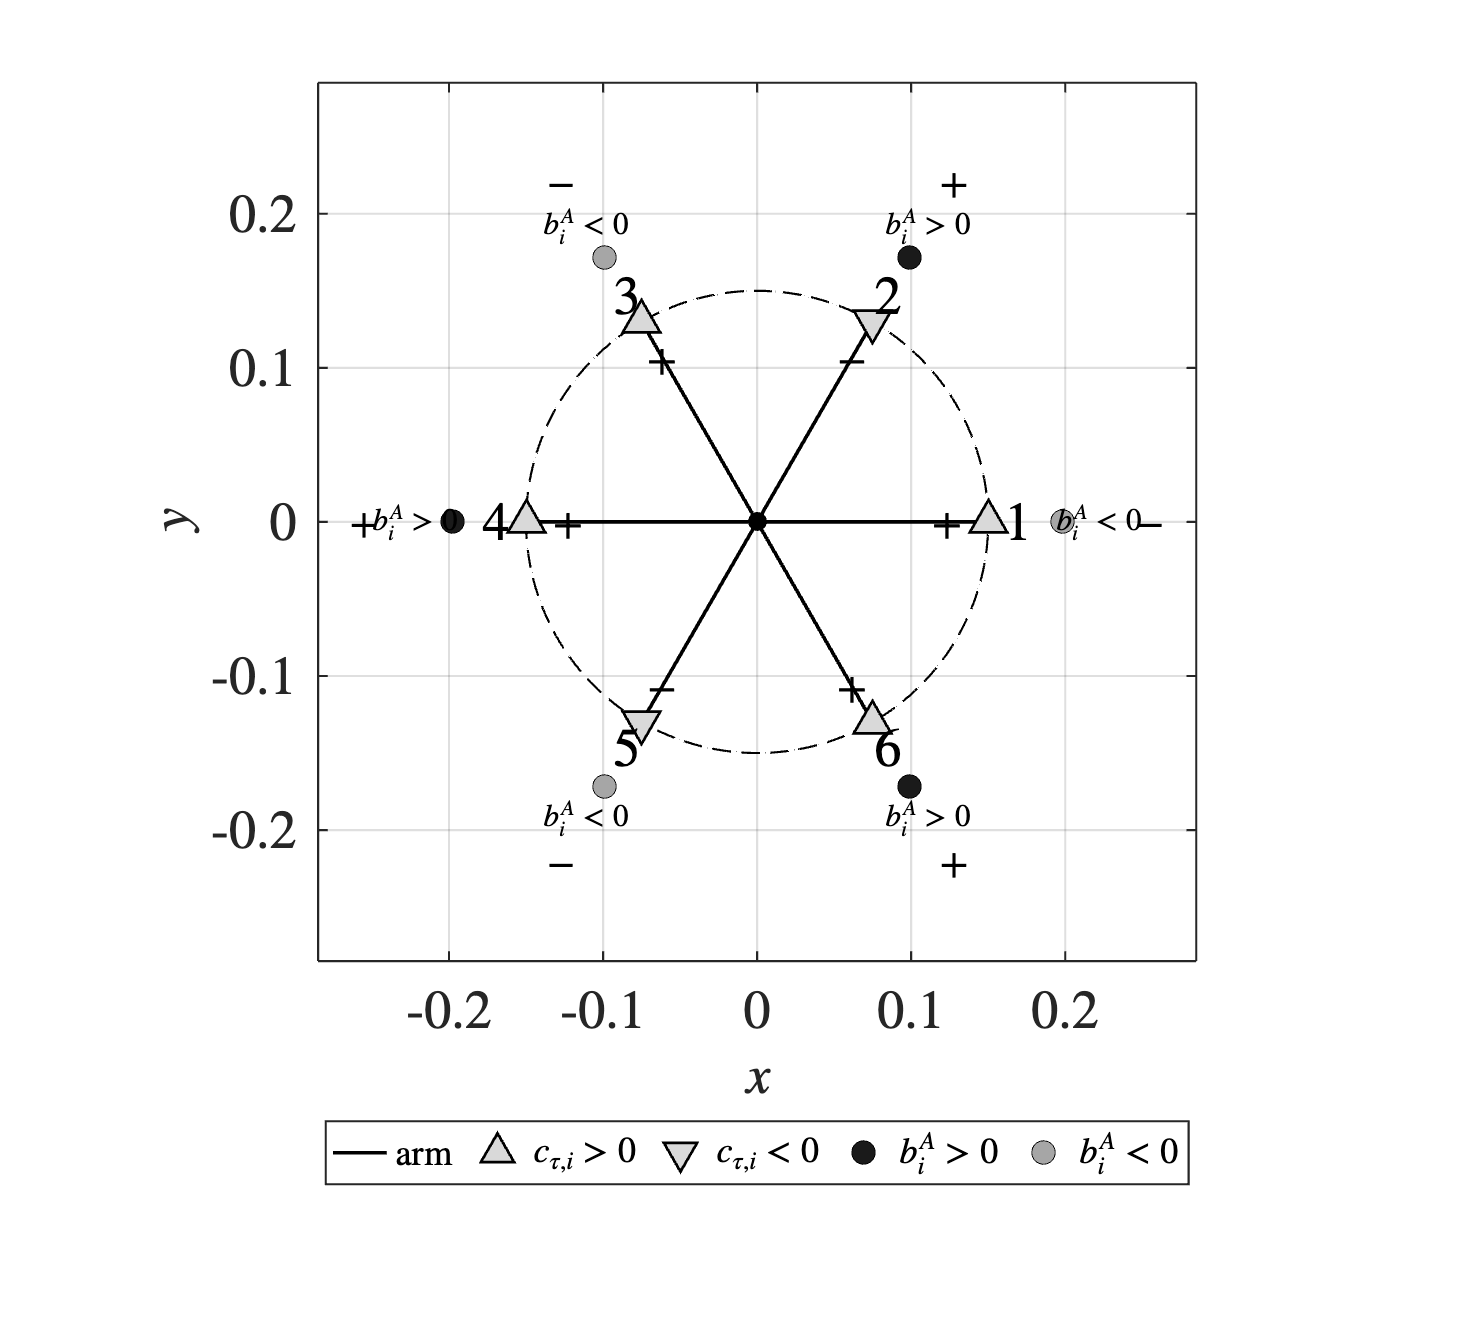


close all
clear all
clc

%% Add project folders to path
rootDir = fileparts(matlab.desktop.editor.getActiveFilename);

addpath(fullfile(rootDir,'Utilities'));
addpath(fullfile(rootDir,'Init Files'));
addpath(fullfile(rootDir,'Figures'));

% For selecting the layer and constant C, change the script below. 
run("initHexarotor.mlx");

% For changing the gains, initial conditions, change the script below. 
run("initSimulation.mlx");

param = struct with fields:
        Aaug: [5×6 double]
          bA: [6×1 double]
        Cbar: 20
    layer_id: 6
           m: 0.8
           J: [3×3 double]
           g: 9.81
         e_3: [3×1 double]
         e_1: [3×1 double]
         b_3: [3×1 double]
       K_F_p: [3×3 double]


R0 =          0.996194698091746                         0        0.0871557427476582
                         0                         1                         0
       -0.0871557427476582                         0         0.996194698091746


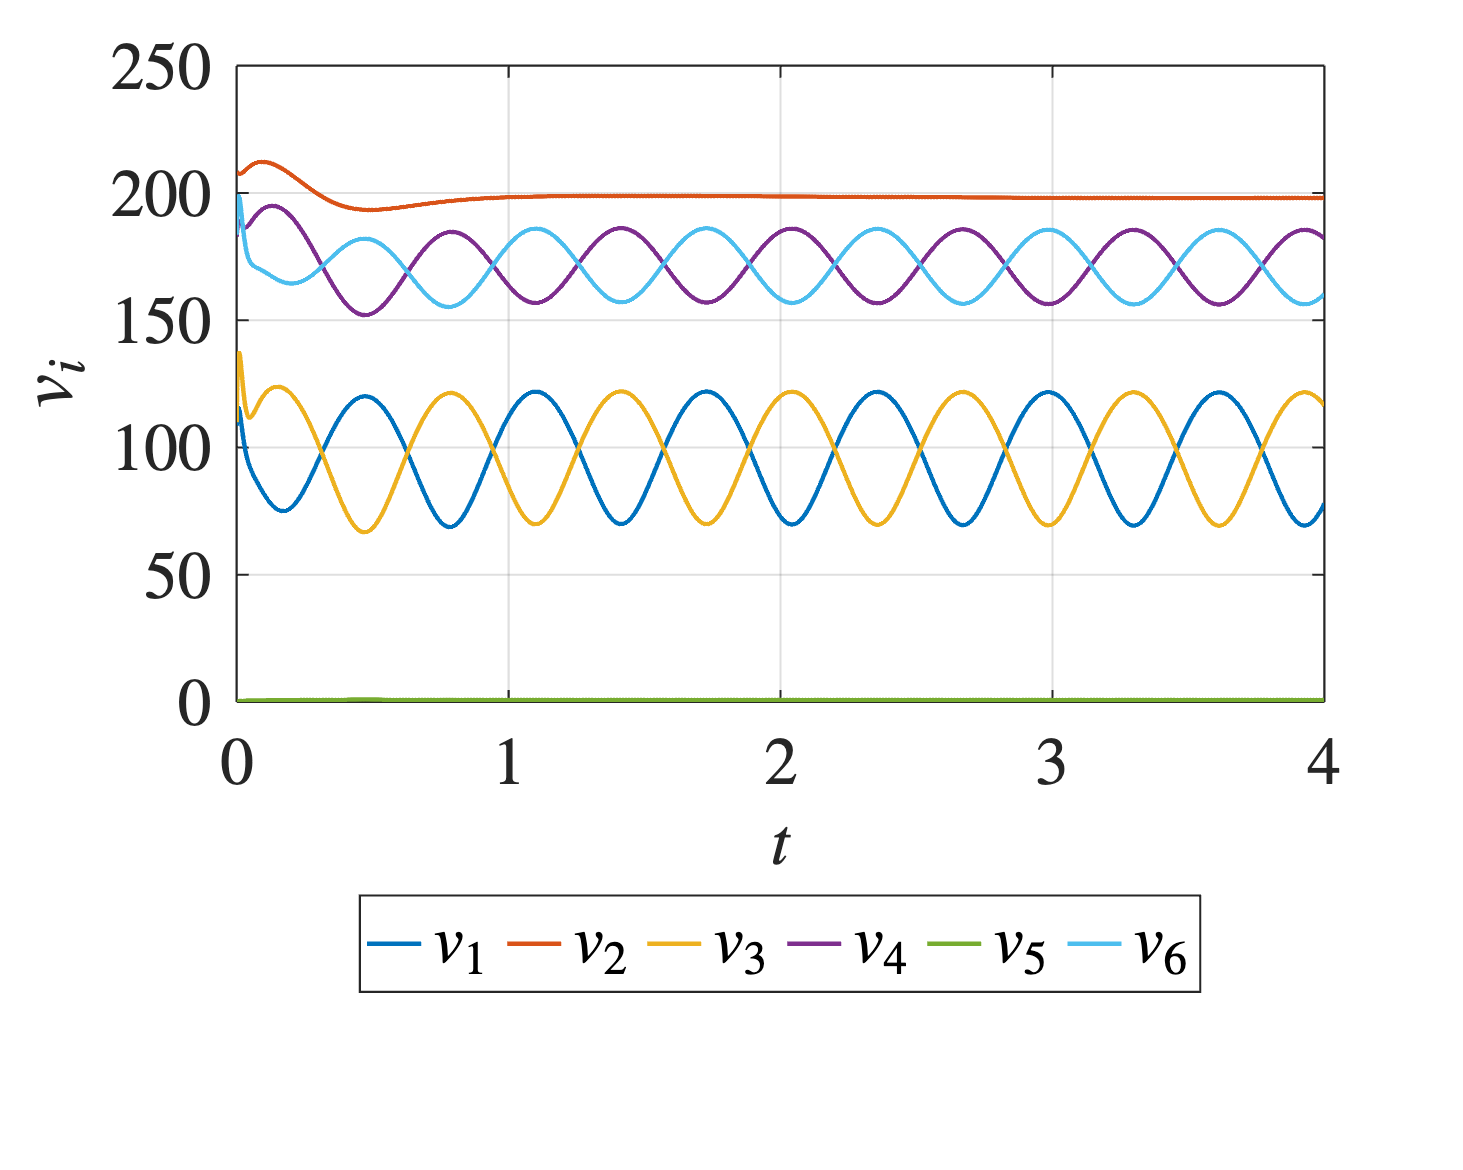

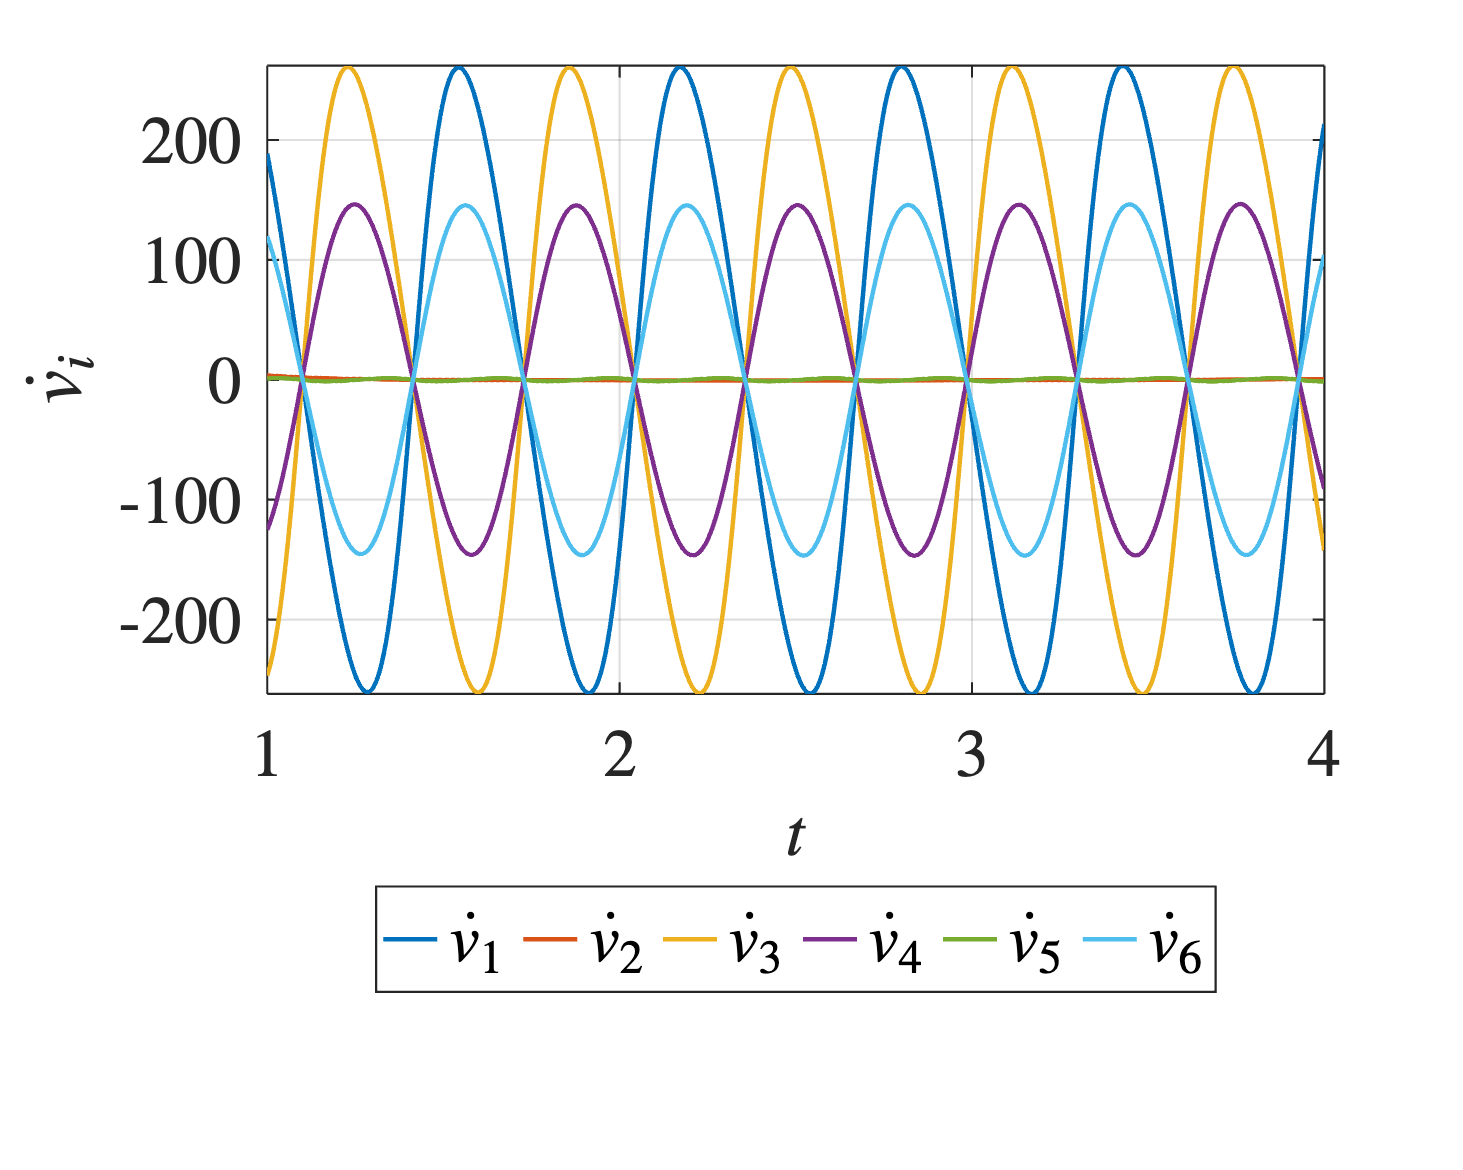

Figure correctly saved in the Figure folder.


out=sim("controller.slx");
plot_hexarotor_velocities_accelerations(out,param.bA,37,param);

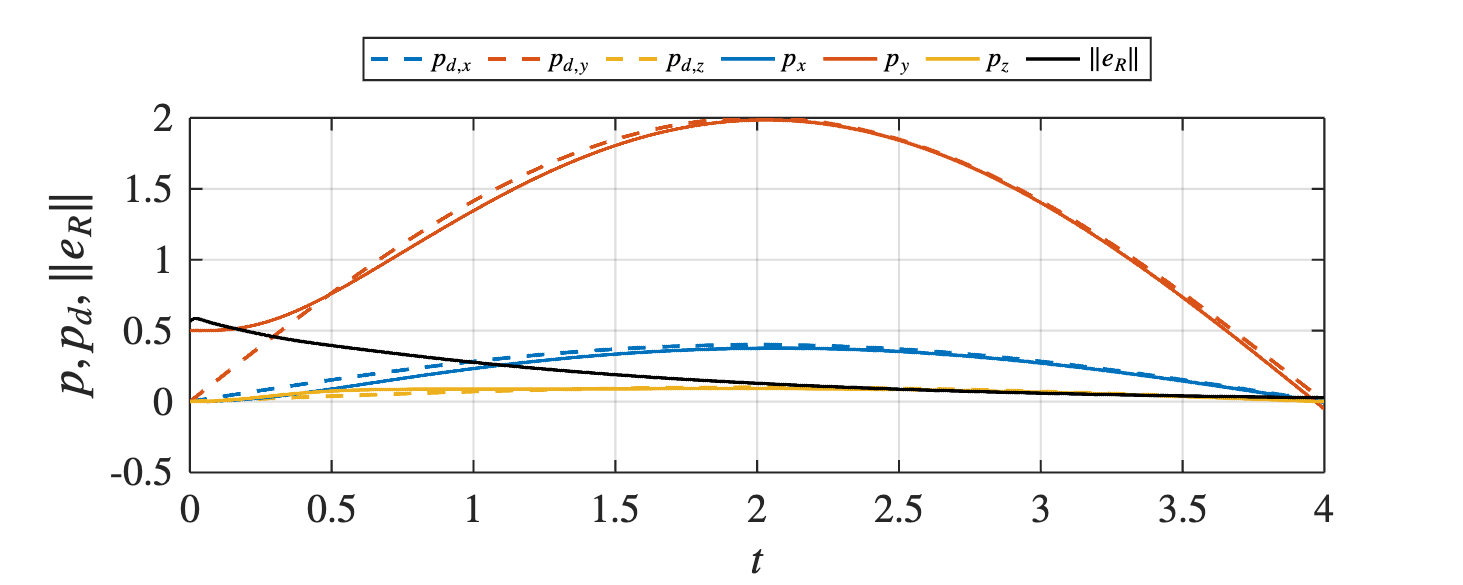

Figure correctly saved in the Figure folder.


plot_position_tracking_with_eR(out,30,param)

time_us = squeeze(out.comp_time_us);
time_us = time_us(100:end);
fprintf('Average allocation time: %.3f us\n', mean(time_us));

Average allocation time: 8.320 us


fprintf('Maximum allocation time: %.3f us\n', max(time_us));

Maximum allocation time: 56.750 us
